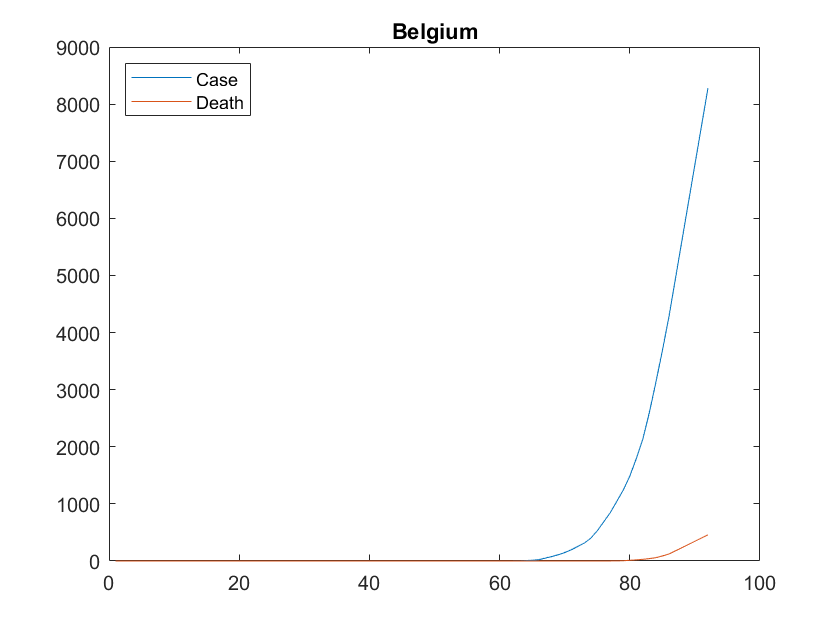

clear
clc

BelgiumDailyCase=sort(BelgiumCase.Cases,'ascend');
BelgiumDailyDeath=sort(BelgiumDeath.Deaths,'ascend');
FranceDailyCase=sort(FranceCase.Cases,'ascend');
FranceDailyDeath=sort(FranceDeath.Deaths,'ascend');
IndiaDailyCase=sort(IndiaCase.Cases,'ascend');
IndiaDailyDeath=sort(IndiaDeath.Deaths,'ascend');
NorwayDailyCase=sort(NorwayCase.Cases,'ascend');
NorwayDailyDeath=sort(NorwayDeath.Deaths,'ascend');



BelgiumCumulativeCase=cumsum(BelgiumDailyCase)';
BelgiumCumulativeDeath=cumsum(BelgiumDailyDeath)';
FranceCumulativeCase=cumsum(FranceDailyCase)';
FranceCumulativeDeath=cumsum(FranceDailyDeath)';
IndiaCumulativeCase=cumsum(IndiaDailyCase)';
IndiaCumulativeDeath=cumsum(IndiaDailyDeath)';
NorwayCumulativeCase=cumsum(NorwayDailyCase)';
NorwayCumulativeDeath=cumsum(NorwayDailyDeath)';


%prepration for  fillmissing

BelgiumCumulativeCase(88:92)=nan;
BelgiumCumulativeDeath(88:92)=nan;
FranceCumulativeCase(88:92)=nan;
FranceCumulativeDeath(88:92)=nan;
IndiaCumulativeCase(87:91)=nan;
IndiaCumulativeDeath(87:91)=nan;
NorwayCumulativeCase(88:92)=nan;
NorwayCumulativeDeath(88:92)=nan;


ProcessedBelgiumCase=fillmissing(BelgiumCumulativeCase,'linear');
ProcessedBelgiumDeath=fillmissing(BelgiumCumulativeDeath,'linear');
ProcessedFranceCase=fillmissing(FranceCumulativeCase,'linear');
ProcessedFranceDeath=fillmissing(FranceCumulativeDeath,'linear');
ProcessedIndiaCase=fillmissing(IndiaCumulativeCase,'linear');
ProcessedIndiaDeath=fillmissing(IndiaCumulativeDeath,'linear');
ProcessedNorwayCase=fillmissing(NorwayCumulativeCase,'linear');
ProcessedNorwayDeath=fillmissing(NorwayCumulativeDeath,'linear');


plot(ProcessedBelgiumCase);
hold on;
plot(ProcessedBelgiumDeath);
legend('Case','Death',"Location","northwest");
title('Belgium');
hold off;

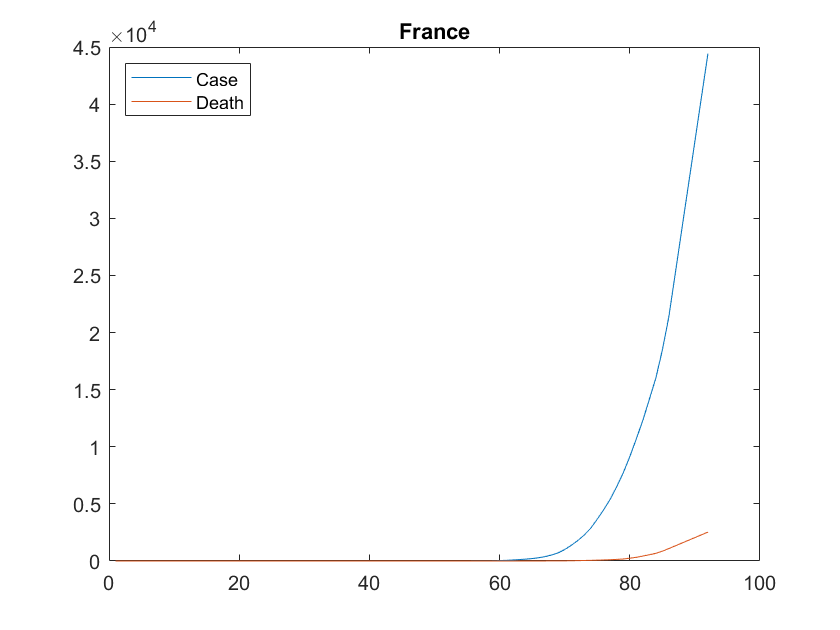

plot(ProcessedFranceCase);
hold on;
plot(ProcessedFranceDeath);
legend('Case','Death',"Location","northwest");
title('France');
hold off;

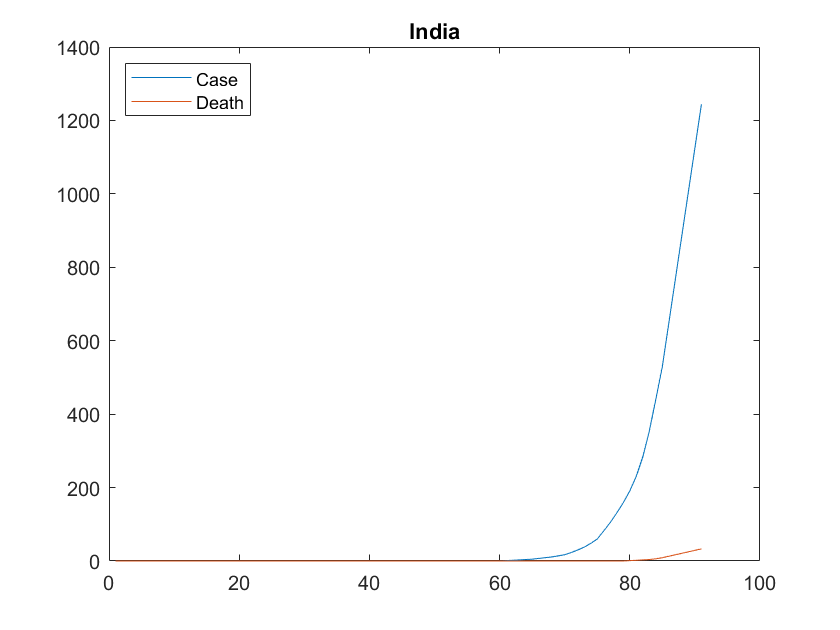

plot(ProcessedIndiaCase);
hold on;
plot(ProcessedIndiaDeath);
legend('Case','Death',"Location","northwest");
title('India');
hold off;

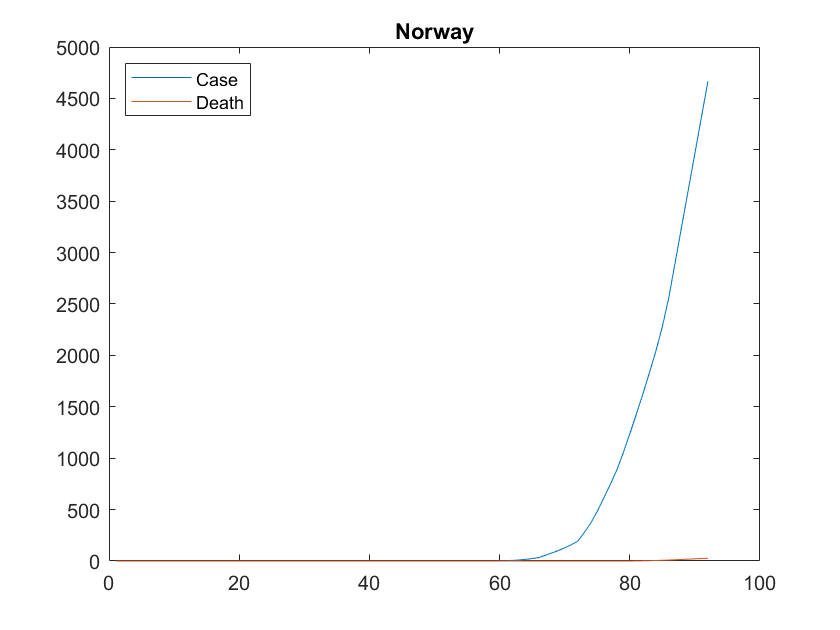

plot(ProcessedNorwayCase);
hold on;
plot(ProcessedNorwayDeath);
legend('Case','Death',"Location","northwest");
title('Norway');
hold off;

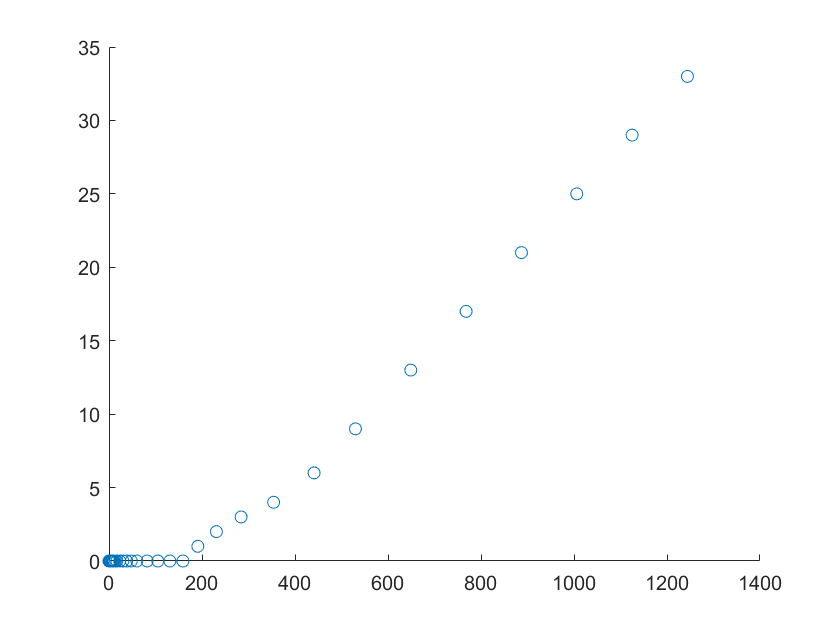


scatter(ProcessedIndiaCase,ProcessedIndiaDeath)

covIndia=cov(ProcessedIndiaCase',ProcessedIndiaDeath')

covIndia = 	1.0e+04 *

    6.3085    0.1490
    0.1490    0.0037


corIndia=corr(ProcessedIndiaCase',ProcessedIndiaDeath')

corIndia = 0.9786


tableCovIndia=array2table(covIndia)

tableCovIndia = 2×2 table
    covIndia1    covIndia2
    _________    _________

      63085       1490.4  
     1490.4       36.767  


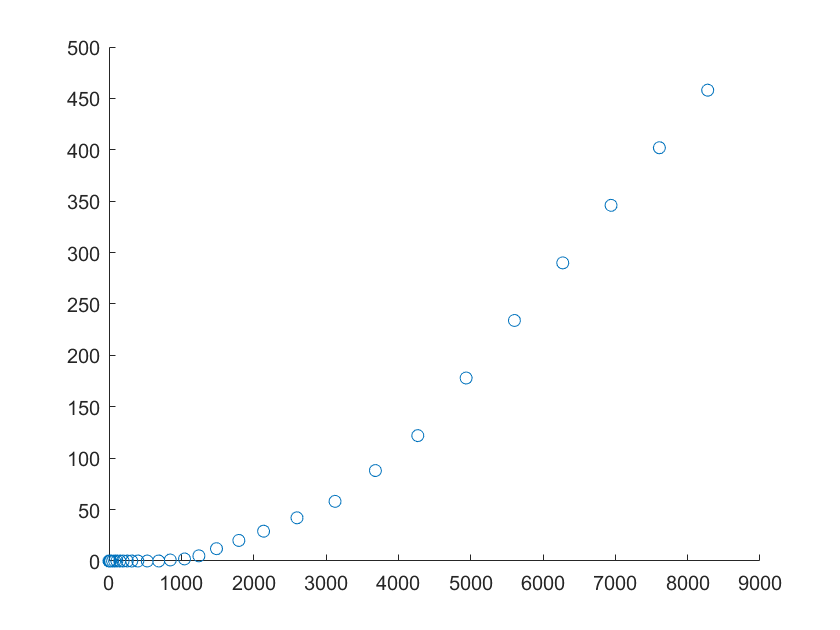

scatter(ProcessedBelgiumCase,ProcessedBelgiumDeath)

covBelgium=cov(ProcessedBelgiumCase',ProcessedBelgiumDeath')

covBelgium = 	1.0e+06 *

    3.1546    0.1419
    0.1419    0.0070


corrBelgium=corr(ProcessedBelgiumCase',ProcessedBelgiumDeath')

corrBelgium = 0.9572


tableCovBelgium=array2table(covBelgium)

tableCovBelgium = 2×2 table
    covBelgium1    covBelgium2
    ___________    ___________

    3.1546e+06      1.419e+05 
     1.419e+05         6966.4 


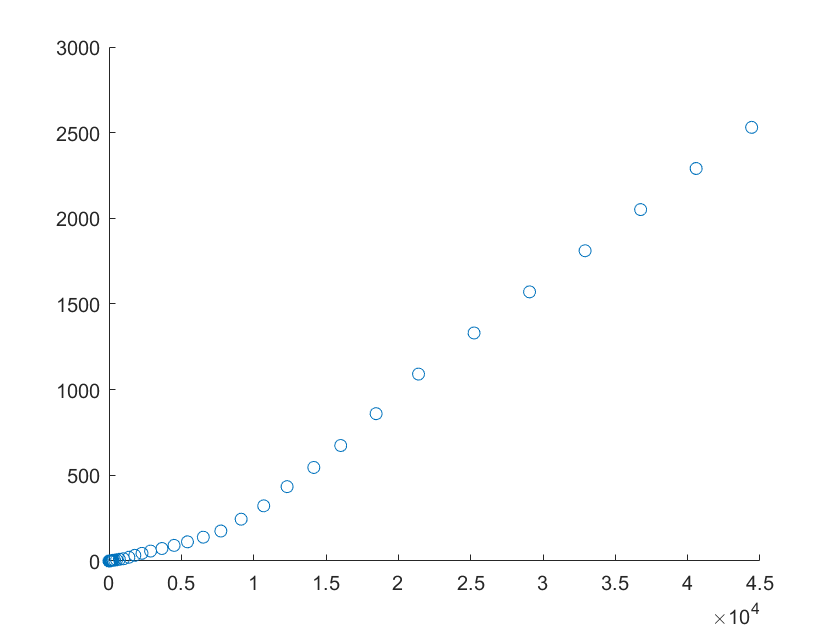

scatter(ProcessedFranceCase,ProcessedFranceDeath)

covFrance=cov(ProcessedFranceCase',ProcessedFranceDeath')

covFrance = 	1.0e+07 *

    8.7780    0.4716
    0.4716    0.0258


corrFrance=corr(ProcessedFranceCase',ProcessedFranceDeath')

corrFrance = 0.9902


tableCovFrance=array2table(covFrance)

tableCovFrance = 2×2 table
    covFrance1    covFrance2
    __________    __________

     8.778e+07    4.7165e+06
    4.7165e+06    2.5847e+05


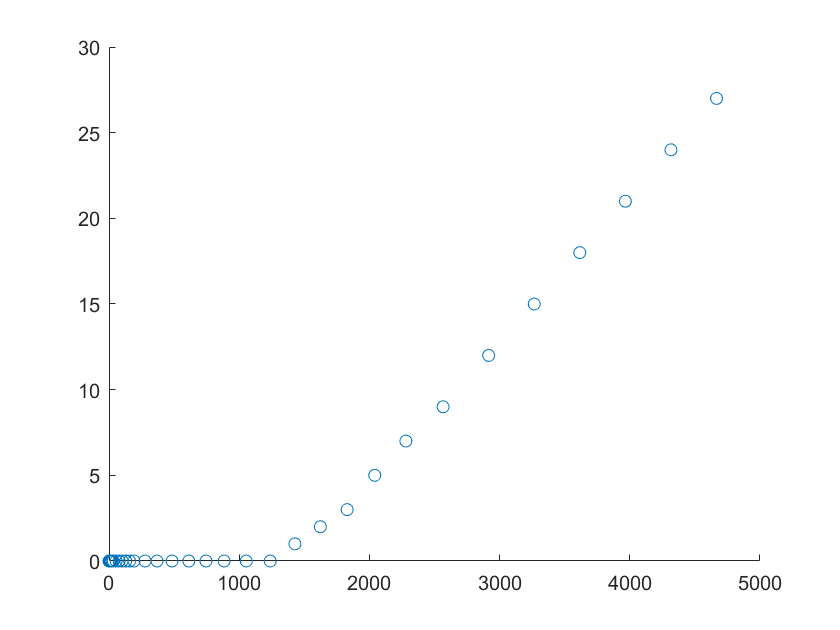

scatter(ProcessedNorwayCase,ProcessedNorwayDeath)

covNorway=cov(ProcessedNorwayCase',ProcessedNorwayDeath')

covNorway = 	1.0e+06 *

    1.0878    0.0050
    0.0050    0.0000


corrNorway=corr(ProcessedNorwayCase',ProcessedNorwayDeath')

corrNorway = 0.9414


tableCovNorway=array2table(covNorway)

tableCovNorway = 2×2 table
    covNorway1    covNorway2
    __________    __________

    1.0878e+06      5024.1  
        5024.1      26.183  


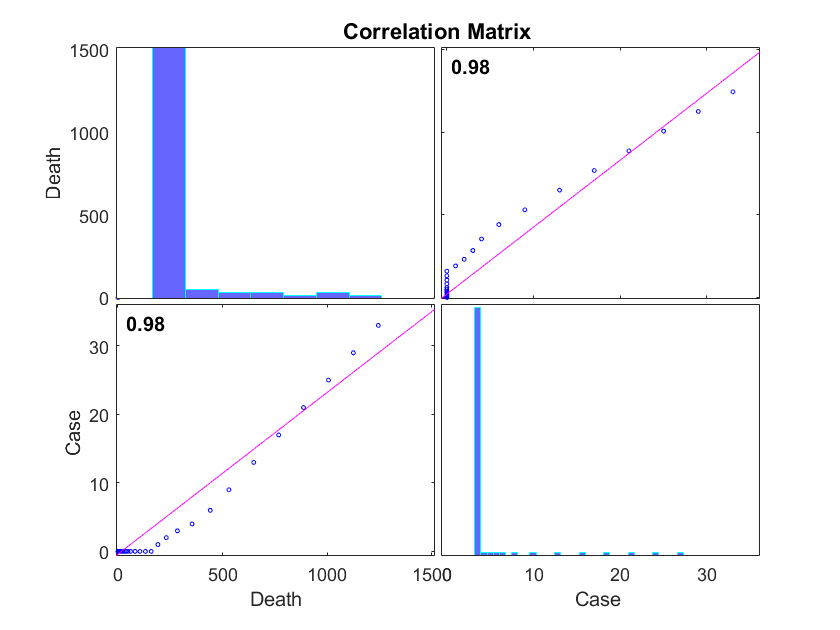

figure('Name','Refined data','NumberTitle','off');
corrplot([ProcessedIndiaCase' ProcessedIndiaDeath'],'varNames',{('Death'),('Case')})


import mlreportgen.report.*
import mlreportgen.dom.*
R=Report('Analyze Covid Virus Data_20180808045','pdf')

R =   Report with properties:

      OutputPath: 'Analyze Covid Virus Data_20180808045'
            Type: 'pdf'
    TemplatePath: []
          Locale: []
           Debug: 0
          Layout: [1×1 mlreportgen.report.ReportLayout]
        Document: [0×0 mlreportgen.dom.Document]
         Context: [0×1 containers.Map]


R.Layout.Landscape = true;
open(R)
tp = TitlePage; 
tp.Title = 'Analyze Covid Virus Data for Some Countries'; 
tp.Author = '  Arda Atasoy       '; 
add(R,tp);
	
p1 = Paragraph([ ... 
'This study relate to some coutries struggles aboub covid-19.' ...
'Process India,Belgium,France,Norway ']); 
add(R,p1)

ch2 = Chapter(); 
ch2.Title = sprintf('covariation relaitionships for India'); 

Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


plot(ProcessedIndiaCase);
hold on;
plot(ProcessedIndiaDeath);
legend('Case','Death',"Location","northwest");
title('India');
hold off;
add(R,Figure);



T=Text("                  ")

T =   Text with properties:

             Content: '                  '
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: []
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:99154'
                  Id: '99154'


tableCov=array2table(covIndia)

tableCov = 2×2 table
    covIndia1    covIndia2
    _________    _________

      63085       1490.4  
     1490.4       36.767  



tbl = Table(tableCovIndia); 

tbl.Style = {... 
    RowSep('solid','black','1px'),... 
    ColSep('solid','black','1px'),}; 
tbl.Border = 'double'; 
tbl.TableEntriesStyle = {HAlign('center')}; 

add(ch2,tbl); 
add(R,ch2); 

p2 = Paragraph([ ... 
'The case in India is more to see the increase' ...
' rate of increase, the number of deaths increase.']); 
add(R,p2)


ch3 = Chapter(); 
ch3.Title = sprintf('covariation relaitionships for Norway');

Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


plot(ProcessedNorwayCase);
hold on;
plot(ProcessedNorwayDeath);
legend('Case','Death',"Location","northwest");
title('Norway');
hold off;
add(R,Figure);



T=Text("                  ")

T =   Text with properties:

             Content: '                  '
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: []
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:99688'
                  Id: '99688'


tableCov=array2table(covNorway)

tableCov = 2×2 table
    covNorway1    covNorway2
    __________    __________

    1.0878e+06      5024.1  
        5024.1      26.183  



tbl = Table(tableCovNorway); 

tbl.Style = {... 
    RowSep('solid','black','1px'),... 
    ColSep('solid','black','1px'),}; 
tbl.Border = 'double'; 
tbl.TableEntriesStyle = {HAlign('center')}; 

add(ch3,tbl); 
add(R,ch3); 

para = Paragraph([ ... 
'Among the countries we have studied, Norway is the country that best tackles this ' ...
'problem. The death rate is very low compared to the number of cases.']);

ch4 = Chapter(); 
ch4.Title = sprintf('covariation relaitionships for France');

Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


plot(ProcessedFranceCase)
hold on
plot(ProcessedFranceDeath)
legend('Case','Death',"Location","northwest")
title('France')
hold off
add(R,Figure)


ch2 = Chapter(); 
ch2.Title = sprintf('covariation relaitionships'); 
T=Text("                  ")

T =   Text with properties:

             Content: '                  '
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: []
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:99887'
                  Id: '99887'


tableCov=array2table(covFrance)

tableCov = 2×2 table
    covFrance1    covFrance2
    __________    __________

     8.778e+07    4.7165e+06
    4.7165e+06    2.5847e+05



tbl = Table(tableCovFrance); 

tbl.Style = {... 
    RowSep('solid','black','1px'),... 
    ColSep('solid','black','1px'),}; 
tbl.Border = 'double'; 
tbl.TableEntriesStyle = {HAlign('center')}; 

add(ch2,tbl); 
add(R,ch2); 



add(R,Chapter('Title','Tests'));
add(R,Chapter('Title','Unit Tests'));
add(R,T)




Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


plot(ProcessedBelgiumCase)
hold on
plot(ProcessedBelgiumDeath)
legend('Case','Death',"Location","northwest")
title('Belgium')
hold off
add(R,Figure)



ch2 = Chapter(); 
ch2.Title = sprintf('Covariation Relaitionships for Belgium'); 
T=Text("                  ")

T =   Text with properties:

             Content: '                  '
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: []
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:100295'
                  Id: '100295'


tableCov=array2table(covBelgium)

tableCov = 2×2 table
    covBelgium1    covBelgium2
    ___________    ___________

    3.1546e+06      1.419e+05 
     1.419e+05         6966.4 



tbl = Table(tableCovBelgium); 

tbl.Style = {... 
    RowSep('solid','black','1px'),... 
    ColSep('solid','black','1px'),}; 
tbl.Border = 'double'; 
tbl.TableEntriesStyle = {HAlign('center')}; 

add(ch2,tbl); 
add(R,ch2); 



Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


plot(ProcessedNorwayCase)
hold on
plot(ProcessedNorwayDeath)
legend('Case','Death',"Location","northwest")
title('Norway')
hold off
add(R,Figure)



ch2 = Chapter(); 
ch2.Title = sprintf('Covariation Relaitionships for Norway'); 
T=Text("                  ")

T =   Text with properties:

             Content: '                  '
                Bold: []
              Italic: []
               Color: []
     BackgroundColor: []
           Underline: []
          WhiteSpace: []
      FontFamilyName: []
            FontSize: []
              Strike: []
           StyleName: []
               Style: {1×0 cell}
    CustomAttributes: []
              Parent: []
            Children: [1×0 mlreportgen.dom.Node]
                 Tag: 'dom.Text:100494'
                  Id: '100494'


tableCov=array2table(covNorway)

tableCov = 2×2 table
    covNorway1    covNorway2
    __________    __________

    1.0878e+06      5024.1  
        5024.1      26.183  



tbl = Table(tableCovNorway); 

tbl.Style = {... 
    RowSep('solid','black','1px'),... 
    ColSep('solid','black','1px'),}; 
tbl.Border = 'double'; 
tbl.TableEntriesStyle = {HAlign('center')}; 

add(ch2,tbl); 
add(R,ch2); 



Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


scatter(ProcessedIndiaCase,ProcessedIndiaDeath)
add(R,Figure);


Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


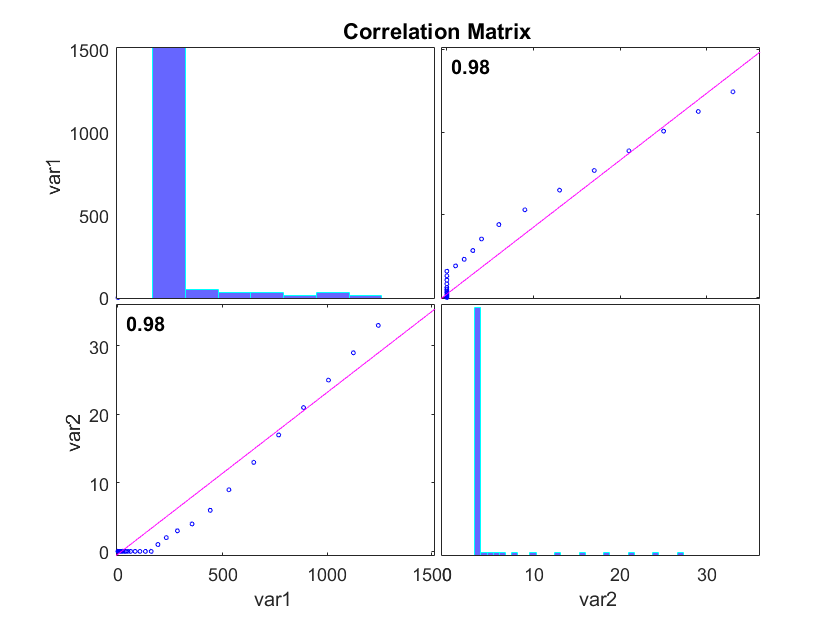

corrplot([ProcessedIndiaCase' ProcessedIndiaDeath']);
add(R,Figure);






Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


scatter(ProcessedNorwayCase,ProcessedNorwayDeath)
add(R,Figure);


Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


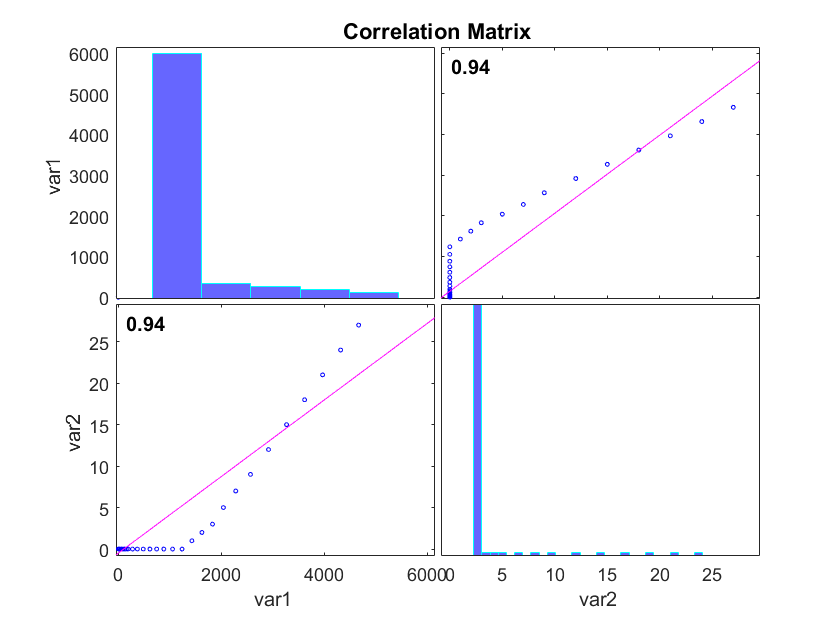

corrplot([ProcessedNorwayCase' ProcessedNorwayDeath']);
add(R,Figure);






Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


scatter(ProcessedFranceCase,ProcessedFranceDeath)
add(R,Figure);


Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


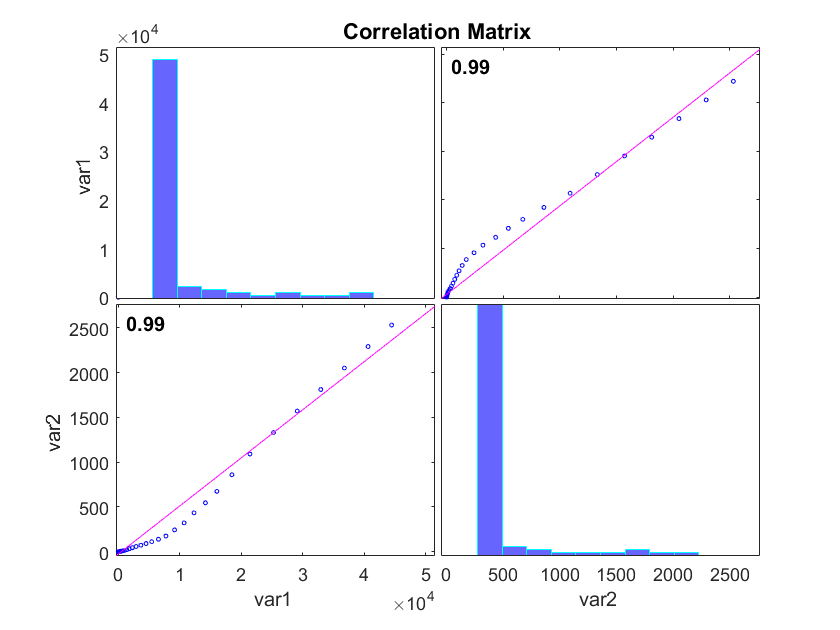

corrplot([ProcessedFranceCase' ProcessedFranceDeath']);
add(R,Figure);




Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


scatter(ProcessedBelgiumCase,ProcessedBelgiumDeath)
add(R,Figure);


Figure

ans =   Figure with properties:

             SnapshotFormat: "svg"
                     Source: []
                   Snapshot: [1×1 mlreportgen.report.FormalImage]
                    Scaling: "auto"
                     Height: "6in"
                      Width: "6.5in"
    PreserveBackgroundColor: 0
                TemplateSrc: []
               TemplateName: "Figure"
                 LinkTarget: []


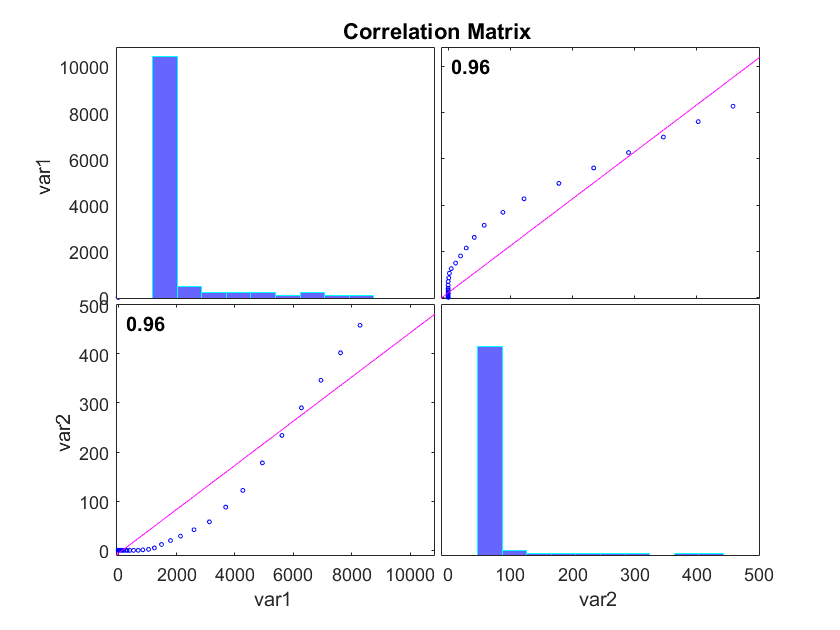

corrplot([ProcessedBelgiumCase' ProcessedBelgiumDeath']);
add(R,Figure);









p10 = Paragraph([ ... 
'Differrent countries growth rates are '... 
'Italy cases grew by 5,322 equalling a growth of 15%' ...
'Spain cases grew by 4,053 equalling a growth of 29%' ...
'Germany cases grew by 2,993 equalling a growth of 24%' ...
'France cases grew by 1,828 equalling a growth of 20%'...
'Switzerland cases grew by 1,047 equalling a growth of 35%'...
'Iran cases grew by 1,046 equalling a growth of 6%'...
'Netherlands cases grew by 409 equalling a growth of 20%'...
'Austria cases grew by 367 equalling a growth of 22%'...
'Portugal cases grew by 337 equalling a growth of 75%'...
'Belgium cases grew by 309 equalling a growth of 21%'...
'Ireland cases grew by 265 equalling a growth of 91%'...
'Brazil cases grew by 249 equalling a growth of 67%'...
'Israel cases grew by 244 equalling a growth of 56%'...
'Czechia cases grew by 230 equalling a growth of 50%'...
'Norway cases grew by 196 equalling a growth of 13%'...
'Sweden cases grew by 160 equalling a growth of 13%'...
'Pakistan cases grew by 155 equalling a growth of 52%'...
'South Korea cases grew by 152 equalling a growth of 2%'...
'Canada cases grew by 143 equalling a growth of 22%'...
'Luxembourg cases grew by 132 equalling a growth of 65%'...
'Australia cases grew by 113 equalling a growth of 20%'...
'Malaysia cases grew by 110 equalling a growth of 14%'...
'Poland cases grew by 104 equalling a growth of 41%'...
'Saudi Arabia cases grew by 103 equalling a growth of 60%'...
'Turkey cases grew by 94 equalling a growth of 96%'...
'Denmark cases grew by 94 equalling a growth of 9%'...
'Peru cases grew by 89 equalling a growth of 61%'...
'Ecuador cases grew by 88 equalling a growth of 79%'...
'Indonesia cases grew by 84 equalling a growth of 37%'...
'Iceland cases grew by 80 equalling a growth of 32%'...
'Finland cases grew by 64 equalling a growth of 19%'...
'United Kingdom cases grew by 63 equalling a growth of 2%'...
'Egypt cases grew by 60 equalling a growth of 31%'...
'Thailand cases grew by 60 equalling a growth of 28%'...
'China cases grew by 54 equalling a growth of 0%'...
'Russia cases grew by 52 equalling a growth of 35%'...
'India cases grew by 38 equalling a growth of 24%'...
'Japan cases grew by 35 equalling a growth of 4%'...
'South Africa cases grew by 34 equalling a growth of 29%'...
'Singapore cases grew by 32 equalling a growth of 10%'...
'Armenia cases grew by 31 equalling a growth of 37%'...
'Iraq cases grew by 28 equalling a growth of 17%'...
'United Arab Emirates cases grew by 27 equalling a growth of 24%'...
'Mexico cases grew by 25 equalling a growth of 27%'...
'Croatia cases grew by 24 equalling a growth of 30%'...
'Lebanon cases grew by 24 equalling a growth of 18%'...
'Panama cases grew by 23 equalling a growth of 27%'...
'Bahrain cases grew by 22 equalling a growth of 9%'...
'Serbia cases grew by 20 equalling a growth of 24%']); 
add(R,p10)
add(R,TableOfContents);
close(R);
rptview(R);

